## Definitions

f = @(z, c) z^2 + c

f = function_handle with value:
    @(z,c)z^2+c


c = @(t) [t 0; 0 t]

c = function_handle with value:
    @(t)[t,0;0,t]


d = @(t) [t 0; 0 t]

d = function_handle with value:
    @(t)[t,0;0,t]


g = @(t) [t 0;0 t]

g = function_handle with value:
    @(t)[t,0;0,t]


res = 100;
ceiling = 10;
iter = 20;


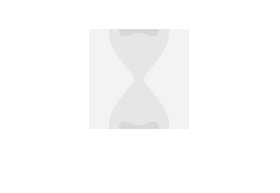

loops = 10;
frames(loops) = struct('cdata', [], 'colormap',[]);
for j=1:loops
    Norm=matrixIterate(f, g, c(j/5), res, ceiling, iter);
    imshow(Norm)
    drawnow
    frames(j) = getframe;
end

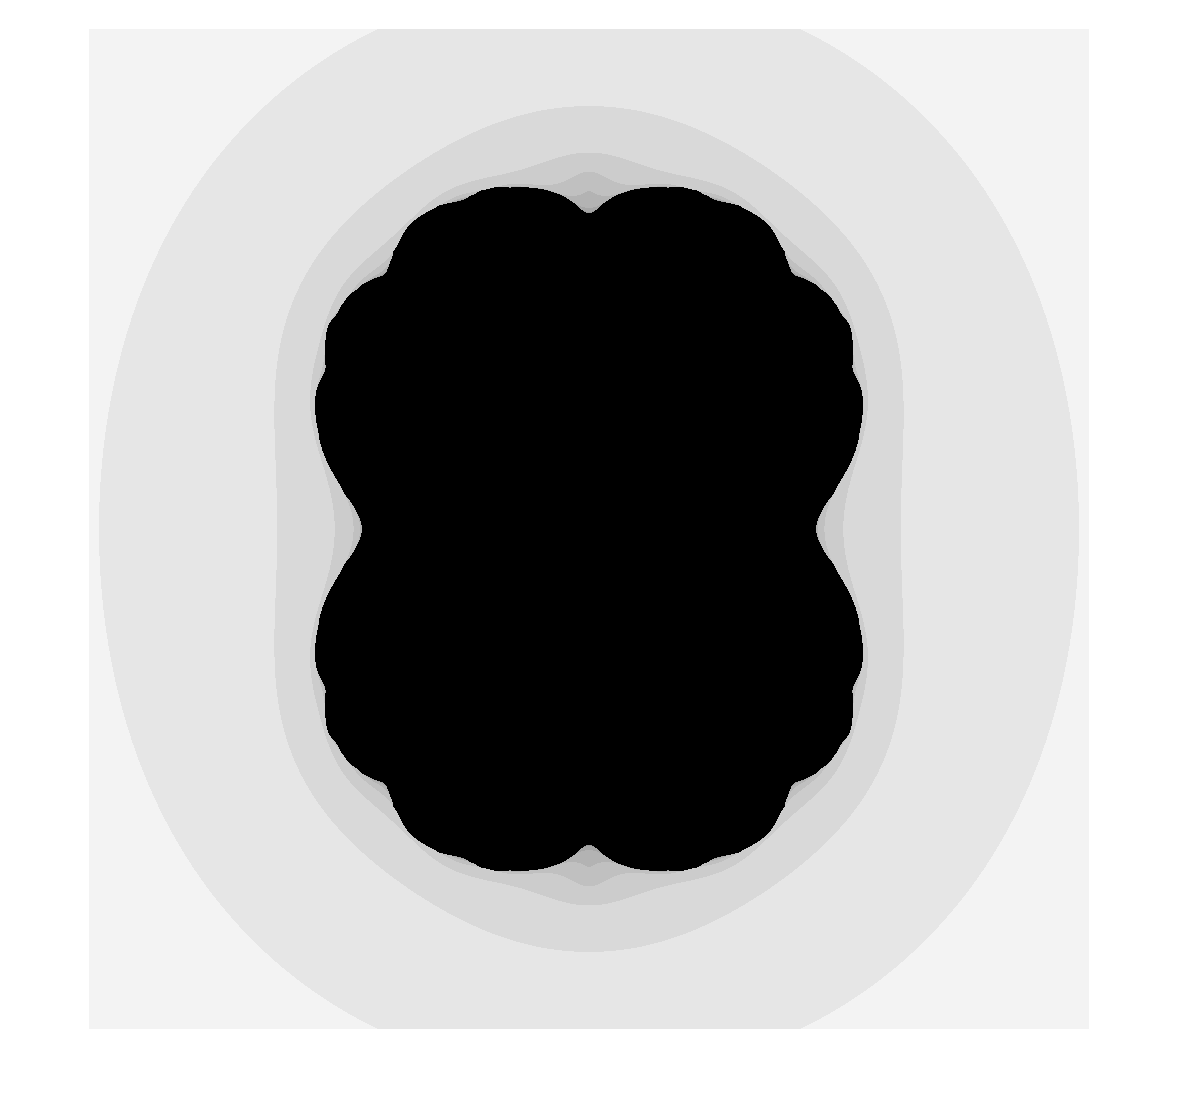

Norm=matrixIterate(f, g, c(.2), res, ceiling, iter);
imshow(Norm)

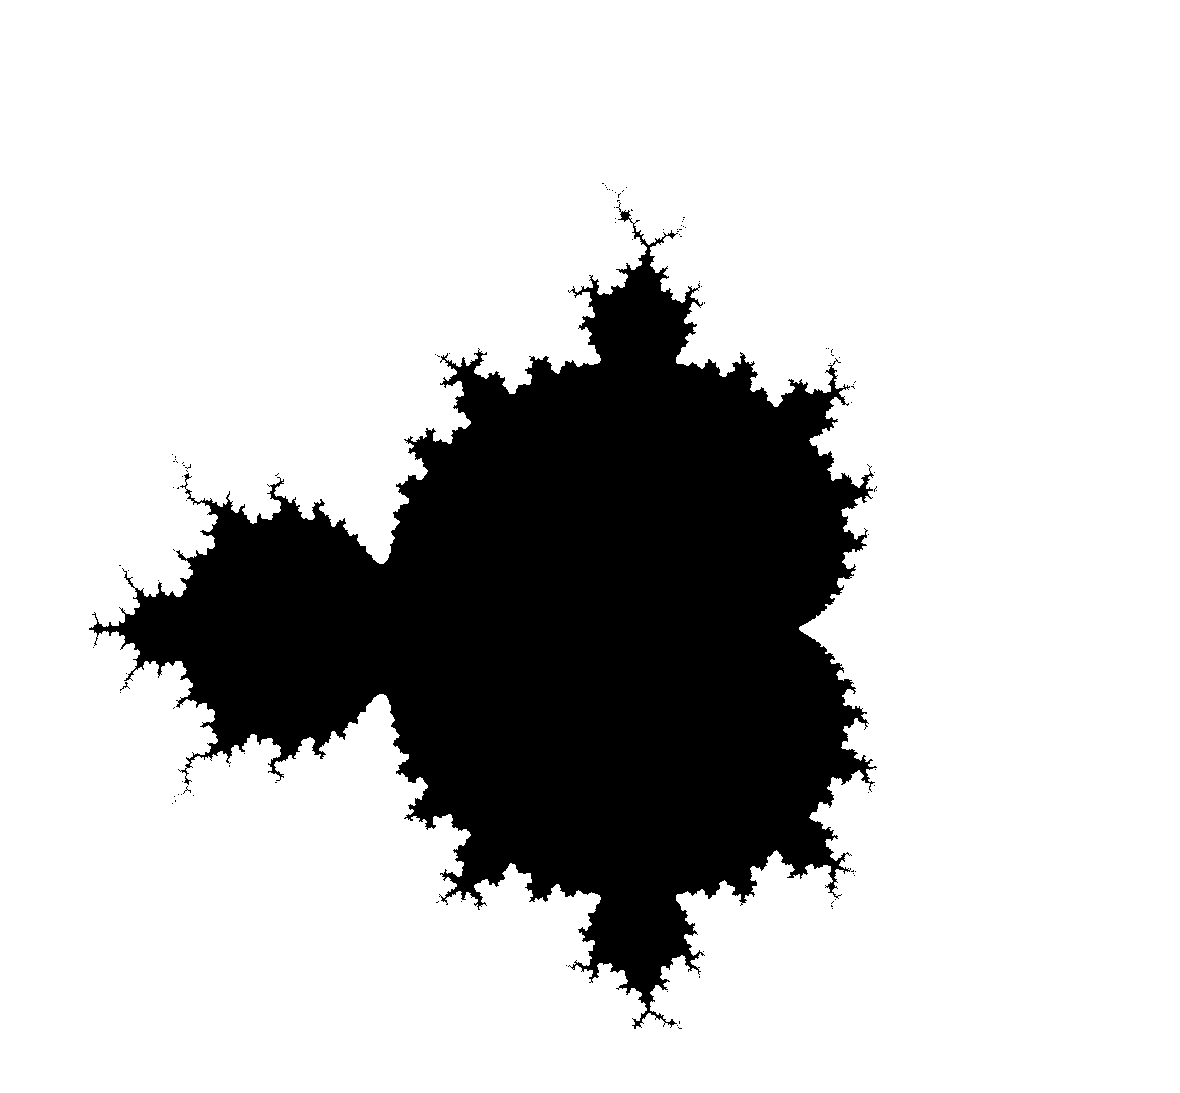

brot = brotSet(f, d, res, ceiling,iter);
imshow(brot)

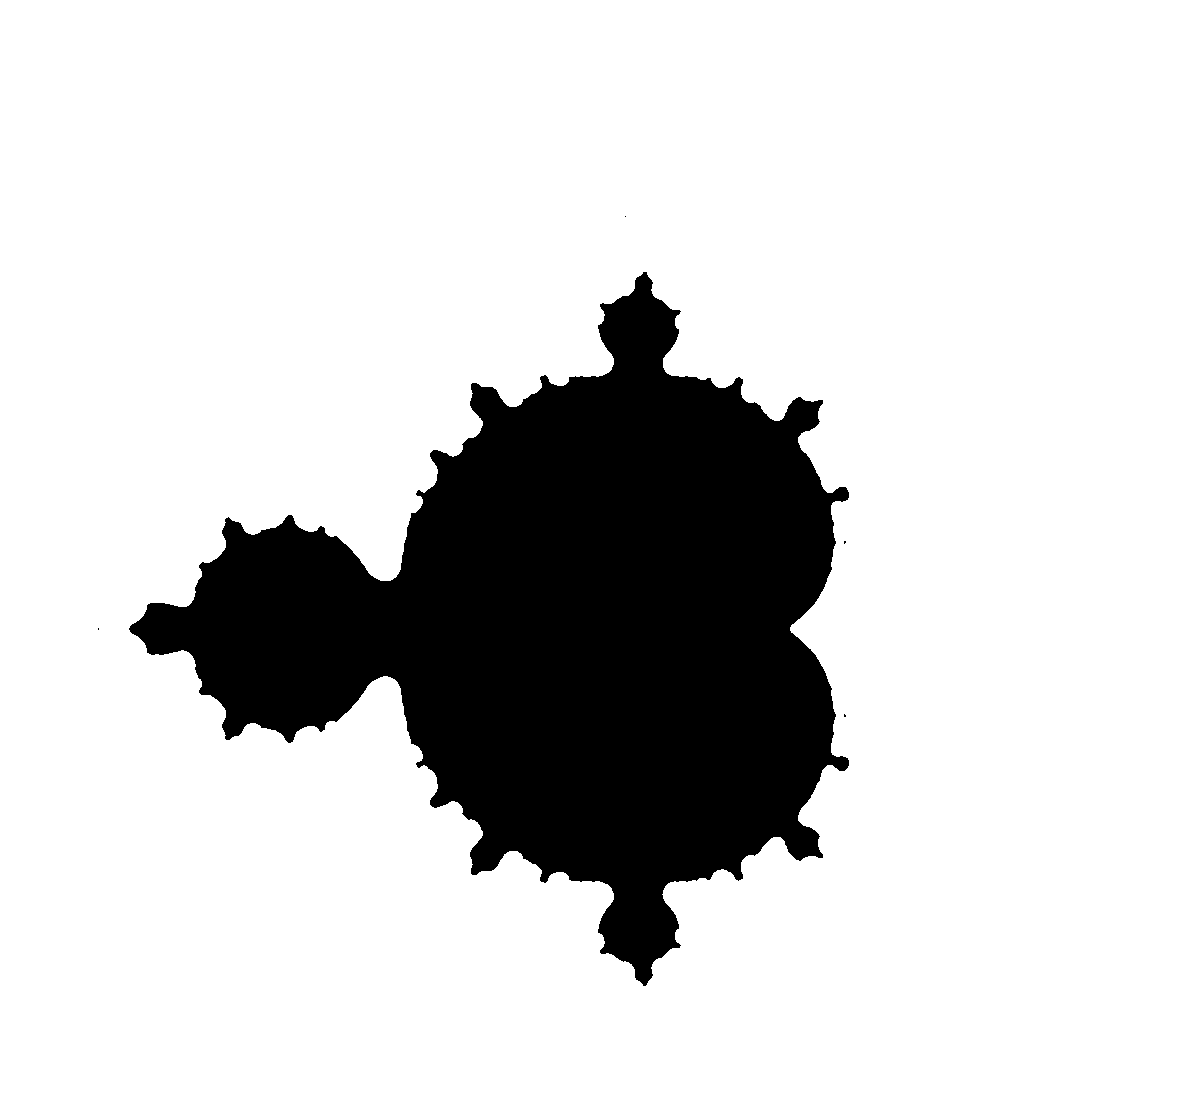


brot = brotSet(f, c, res, ceiling,iter);
imshow(brot)

function Norm = matrixIterate(f, g, c, res, ceiling, iter)
    x = linspace(-1.5,1.5,res);
    y = linspace(-1.5,1.5,res);
    [X, Y] = meshgrid(x,y);
    Z = X + 1i*Y;
    Norm = zeros(res);
    for row=1:res
        for col=1:res
            T = Z(row,col);
            current = f(g(T), c);
            for i = 1:iter
                if norm(current,'fro') > ceiling
                    break
                else
                   current = f(current, c);
                end
                Norm(row,col) = 1-i/iter;
            end
        end
    end
end

function [i,brot] = matrixMandelbrotQ(f, c, ceiling, iter)
   Zero = zeros(2);
   current = f(Zero,c);
   for i=1:iter
       if norm(current,'fro') > ceiling
           break
       else
           current = f(current, c);
       end
   end
   if i ~= iter
       brot = 0;
   else
       brot = 1;
   end
end

function brot = brotSet(f, c, res, ceiling, iter)
    x = linspace(-1.5,1,res);
    y = linspace(-1.5,1,res);
    [X, Y] = meshgrid(x,y);
    Z = X + 1i*Y;
    brot = zeros(res);
    for row=1:res
        for col=1:res
            [k, member] = matrixMandelbrotQ(f, c(Z(row,col)), ceiling, iter);
            brot(row,col) = 1-member;
        end
    end
end